%==========================================================================
% Author:    N. Akhavan (UMich)
% Project:   Human sleep architecture — REM fraction across the night
%
% Goal:
%   Quantify how the fraction of time spent in REM changes across the sleep
%   episode, after applying a strict long-wake exclusion (LW DROP ≥ 2 min).
%
% What this script computes:
%   1) Long-wake DROP (cycle-level):
%      Drop any REM cycle whose StageDetails contains a *single contiguous*
%      Wake block (Stage==5) with Duration ≥ 2 minutes inside the IREM portion.
%
%   2) Normalize each subject's night to [0,1] time:
%      The "episode clock" is built by accumulating per-cycle duration:
%           cycle_duration = IREM + REM_duration
%      Then the night is partitioned into equal-length bins in normalized time.
%
%   3) For each subject and each bin:
%      Compute REM-time-in-bin / bin-duration (a subject-level fraction).
%
%   4) Group statistics for the BAR plot:
%      Bars show the mean of subject-level fractions (subject-mean),
%      and error bars show SE across subjects:
%           SE = std_across_subjects / sqrt(N_subjects).
%
% Outputs:
%   - Figure: subject-mean REM% by normalized-time bins, with SE error bars
%   - CSV table with subject-mean REM%, SE, and optional pooled-time metrics
%
% IMPORTANT (Figure 9(b) note):
%   The number of normalized-time bins is controlled by nDec (and decileEdges01).
%   If you change nDec from 3 to 10 (and set decileEdges01 = linspace(0,1,nDec+1)),
%   you will obtain a 10-bin version of this plot corresponding to Figure 9(b).
%
% Inputs:
%   - Combined_BigResultTable.mat (cycle-level metrics)
%   - Combined_BigStageDetailsTable.mat (stage blocks with durations)
%
% Conventions:
%   - Time units are seconds internally.
%   - REM duration is taken from REMdur if present; otherwise REMpost is used.
%
% Last updated: 2026-01-19
%==========================================================================
close all; clear; clc;


## Paths & knobs

combinedFolder  = 'C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out';
matR            = fullfile(combinedFolder,'Combined_BigResultTable.mat');
matD            = fullfile(combinedFolder,'Combined_BigStageDetailsTable.mat');

WAKE_BREAK_MIN  = 2;                % minutes
WAKE_BREAK_SEC  = WAKE_BREAK_MIN*60;

SAVE_FIG = true;
SAVE_TAB = true;

decileEdges01 = linspace(0,1,4);
decileMidsPct = 100*(decileEdges01(1:end-1)+decileEdges01(2:end))/2;
nDec          = 3;


## Load combined tables (Human)

assert(isfile(matR), 'Missing %s', matR);
assert(isfile(matD), 'Missing %s', matD);

SR = load(matR);  R = SR.Combined_BigResultTable;
SD = load(matD);  D = SD.Combined_BigStageDetailsTable;

%% --------------------- Normalize R types ------------------------
R.Subject_Index = string(R.Subject_Index);

if ~ismember("REM_Cycle_Index", string(R.Properties.VariableNames))
    R.REM_Cycle_Index = strings(height(R),1);
end
R.REM_Cycle_Index = string(R.REM_Cycle_Index);

% Ensure IREM exists (NREM+Wake+Movement if needed)
needR = ["IREM","NREM","Wake","Movement"];
for v = needR
    if ~ismember(v, string(R.Properties.VariableNames))
        R.(v) = NaN(height(R),1);
    end
    R.(v) = double(R.(v));
end
if (~ismember("IREM", string(R.Properties.VariableNames))) || all(isnan(R.IREM))
    if all(ismember(["NREM","Wake","Movement"], string(R.Properties.VariableNames)))
        R.IREM = double(R.NREM) + double(R.Wake) + double(R.Movement);
    else
        error('Cannot reconstruct IREM: missing NREM/Wake/Movement.');
    end
else
    R.IREM = double(R.IREM);
end


## Find REM duration column

% Prefer REMdur if present; otherwise use REMpost.
candREM = ["REMdur","REMpost","REM","REM_Duration","REMlen","REM_sec","REMduration"];
haveREM = candREM(ismember(candREM, string(R.Properties.VariableNames)));
if isempty(haveREM)
    error('No REM duration column found (looked for: %s).', strjoin(candREM, ', '));
end
REMcolName = haveREM(1);
fprintf('Using column "%s" as REM duration.\n', REMcolName);

Using column "REMpost" as REM duration.


R.(REMcolName) = double(R.(REMcolName));

%% Normalize D & long-wake DROP
if ~ismember("Stage",    string(D.Properties.VariableNames))
    error('Stage column not found in stage table.');
end
if ~ismember("Duration", string(D.Properties.VariableNames))
    error('Duration column not found in stage table.');
end
if ~ismember("REM_Cycle_Index", string(D.Properties.VariableNames))
    error('Stage table missing REM_Cycle_Index.');
end

D.Stage           = double(D.Stage);
D.Duration        = double(D.Duration);
D.REM_Cycle_Index = string(D.REM_Cycle_Index);

% Ensure block order column
if ~ismember("ord", string(D.Properties.VariableNames))
    D.ord = (1:height(D))';
end
D = sortrows(D, {'REM_Cycle_Index','ord'});

WAKE_CODE = 5;   % adjust if your scoring code differs

[Gd, keys]  = findgroups(D.REM_Cycle_Index);
hasLongWake = false(numel(keys),1);
for gi = 1:numel(keys)
    rows = find(Gd==gi);
    st   = D.Stage(rows);
    du   = D.Duration(rows);
    if any(isfinite(st) & isfinite(du) & st==WAKE_CODE & du>=WAKE_BREAK_SEC)
        hasLongWake(gi) = true;
    end
end

FlagTab = table(keys, hasLongWake, 'VariableNames',{'REM_Cycle_Index','HasLongWake'});
R = outerjoin(R, FlagTab, 'Keys','REM_Cycle_Index', 'MergeKeys',true, 'Type','left');

if ~ismember("HasLongWake", string(R.Properties.VariableNames))
    R.HasLongWake = false(height(R),1);
else
    R.HasLongWake = logical(fillmissing(double(R.HasLongWake), 'constant', 0));
end

maskDrop = (R.HasLongWake == 1);
nDrop    = sum(maskDrop);
Rkeep    = R(~maskDrop, :);
fprintf('Long-wake DROP: Wake >= %d min (>= %d s) — dropped %d cycles; kept %d.\n', ...
        WAKE_BREAK_MIN, WAKE_BREAK_SEC, nDrop, height(Rkeep));

Long-wake DROP: Wake >= 2 min (>= 120 s) — dropped 1028 cycles; kept 3994.



%% Valid cycles & groups
for v = ["Subject_Index","IREM",REMcolName]
    assert(ismember(v, string(Rkeep.Properties.VariableNames)), ...
           'Missing %s after filtering.', v);
end

Rkeep.Subject_Index = string(Rkeep.Subject_Index);
Rkeep.IREM          = double(Rkeep.IREM);
Rkeep.(REMcolName)  = double(Rkeep.(REMcolName));

valid = isfinite(Rkeep.IREM) & (Rkeep.IREM>=0) & ...
        isfinite(Rkeep.(REMcolName)) & (Rkeep.(REMcolName) > 0);
Rkeep = Rkeep(valid,:);
assert(~isempty(Rkeep),'No valid cycles with REM duration after LW filtering.');

[ G, recNames ] = findgroups(Rkeep.Subject_Index);


sumREM_bin   = zeros(nDec,1);   % pooled REM time per decile (optional)
sumTOT_bin   = zeros(nDec,1);   % pooled total bin duration (optional)

subjFracREM  = NaN(numel(recNames), nDec);
used         = false(numel(recNames),1);


## Per-subject decile stats

for gi = 1:numel(recNames)
    idx  = find(G==gi);
    IREM = Rkeep.IREM(idx);
    REM  = Rkeep.(REMcolName)(idx);

    cycDur = IREM + REM;
    cycDur(~isfinite(cycDur)) = 0;

    sCum = [0; cumsum(cycDur)];
    totalNight = sCum(end);
    if totalNight <= 0, continue; end

    decAbs = decileEdges01 * totalNight;   % absolute sec for each decile edge

    REM_st = sCum(1:end-1) + IREM;
    REM_en = REM_st + REM;

    for d = 1:nDec
        a = decAbs(d); b = decAbs(d+1);
        binDur = b - a;
        if binDur <= 0, continue; end

        rem_in_bin = 0;
        for c = 1:numel(REM_st)
            rem_in_bin = rem_in_bin + overlap_len(REM_st(c), REM_en(c), a, b);
        end

        % optional pooled totals 
        sumREM_bin(d) = sumREM_bin(d) + rem_in_bin;
        sumTOT_bin(d) = sumTOT_bin(d) + binDur;

        % SUBJECT-LEVEL fraction for this bin (needed)
        subjFracREM(gi,d) = rem_in_bin / binDur;
    end
    used(gi) = true;
end

nSubj = sum(used);
if nSubj == 0
    error('No subjects with computable REM fractions after LW filtering.');
end


## SUBJECT-AVERAGE (BAR) + SE

meanSubj_pct = 100 * mean(subjFracREM(used,:), 1, 'omitnan');
seSubj_pct   = 100 * std(  subjFracREM(used,:), 0, 1, 'omitnan') / sqrt(nSubj);

% BAR should match the marker method:
barPct = meanSubj_pct;

% (Optional) still compute pooled time-weighted percent if you want it saved
fracREM_pooled     = sumREM_bin ./ max(sumTOT_bin, eps);
fracREM_pooled_pct = 100 * fracREM_pooled;


## Plot

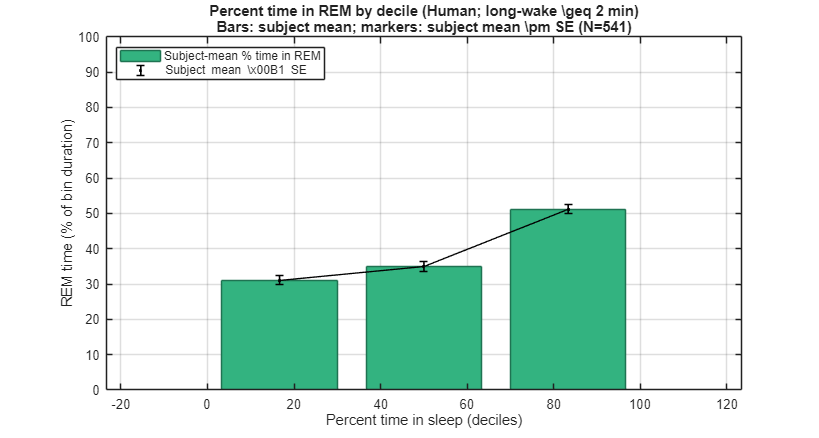

Saved figure: C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out\tables_out\Fig_REM_percentTime_longwake2min_fromCombined.png


figure('Color','w','Position',[100 100 860 460]);

bar(decileMidsPct, barPct, ...
    'FaceColor',[0.20 0.70 0.50], 'EdgeColor',[0.12 0.45 0.32]);
hold on;

% errorbars now correspond to the same subject-mean quantities as the bars
errorbar(decileMidsPct, meanSubj_pct, seSubj_pct, ...
         'k.', 'LineStyle','none', 'LineWidth',1.2);
plot(decileMidsPct, meanSubj_pct, 'k-', 'LineWidth',1);

xlabel('Percent time in sleep (deciles)');
ylabel('REM time (% of bin duration)');

ttl1 = sprintf('Percent time in REM by decile (Human; long-wake \\geq %d min)', WAKE_BREAK_MIN);
ttl2 = sprintf('Bars: subject mean; markers: subject mean \\pm SE (N=%d)', nSubj);
title({ttl1, ttl2}, 'Interpreter','none');

ylim([0, 100]);
grid on; box on;
legend({'Subject-mean % time in REM','Subject mean \x00B1 SE'}, 'Location','northwest');

if SAVE_FIG
    outPng = fullfile(combinedFolder,'tables_out', ...
        sprintf('Fig_REM_percentTime_longwake%dmin_fromCombined.png', WAKE_BREAK_MIN));
    if ~isfolder(fileparts(outPng)), mkdir(fileparts(outPng)); end
    try
        exportgraphics(gcf, outPng, 'Resolution', 300);
    catch
        print(gcf, outPng, '-dpng', '-r300');
    end
    fprintf('Saved figure: %s\n', outPng);
end

## Save table

if SAVE_TAB
    % Keep BOTH versions in the table so you can compare if needed.
    T_out = table((1:nDec).', decileMidsPct(:), ...
        meanSubj_pct(:), seSubj_pct(:), repmat(nSubj,nDec,1), ...
        sumREM_bin(:), sumTOT_bin(:), ...
        fracREM_pooled(:), fracREM_pooled_pct(:), ...
        'VariableNames', {'Decile','MidPercent', ...
                          'Bar_SubjMean_REM_pct','SE_SubjMean_REM_pct','N_subjects', ...
                          'Pooled_REM_sec','Pooled_Total_sec', ...
                          'Pooled_REM_frac','Pooled_REM_pct'});
    outCsv = fullfile(combinedFolder,'tables_out', ...
        sprintf('rem_percent_time_deciles_longwake%dmin_fromCombined.csv', WAKE_BREAK_MIN));
    if ~isfolder(fileparts(outCsv)), mkdir(fileparts(outCsv)); end
    writetable(T_out, outCsv);
    fprintf('Saved table: %s\n', outCsv);
end

Saved table: C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out\tables_out\rem_percent_time_deciles_longwake2min_fromCombined.csv



fprintf('Done. Used N=%d subjects.\n', nSubj);

Done. Used N=541 subjects.


## Function

function L = overlap_len(a1,a2,b1,b2)
% Length of overlap between [a1,a2] and [b1,b2]
if ~(isfinite(a1)&&isfinite(a2)&&isfinite(b1)&&isfinite(b2)) || a2<=a1 || b2<=b1
    L = 0; return;
end
L = max(0, min(a2,b2) - max(a1,b1));
end

